alpha = 2;
frequency = 15 * alpha;
duration = 2; % Duration in seconds
sampling_rate = 120; % Samples per second

% Generate the time vector
t = 0:1/sampling_rate:duration-1/sampling_rate;

% Generate the unit amplitude sinusoidal signal
signal = sin(2 * pi * frequency * t);
dft=fft(signal);

% Task 1: Plot magnitude of DFT for the first 120 samples
N1 = 120; % Number of samples
dft1 = fft(signal(1:N1));
frequencies1 = (0:N1-1) * sampling_rate / N1;
magnitude1 = abs(dft1);

% Task 2: Plot magnitude of DFT for the first 130 samples
N2 = 130; % Number of samples
dft2 = fft(signal(1:N2));
frequencies2 = (0:N2-1) * sampling_rate / N2;
magnitude2 = abs(dft2);

figure;
subplot(2, 1, 1);
plot(frequencies1, magnitude1);
title('Magnitude of DFT (N = 120 samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0 65])

subplot(2, 1, 2);
plot(frequencies2, magnitude2);
title('Magnitude of DFT (N = 130 samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

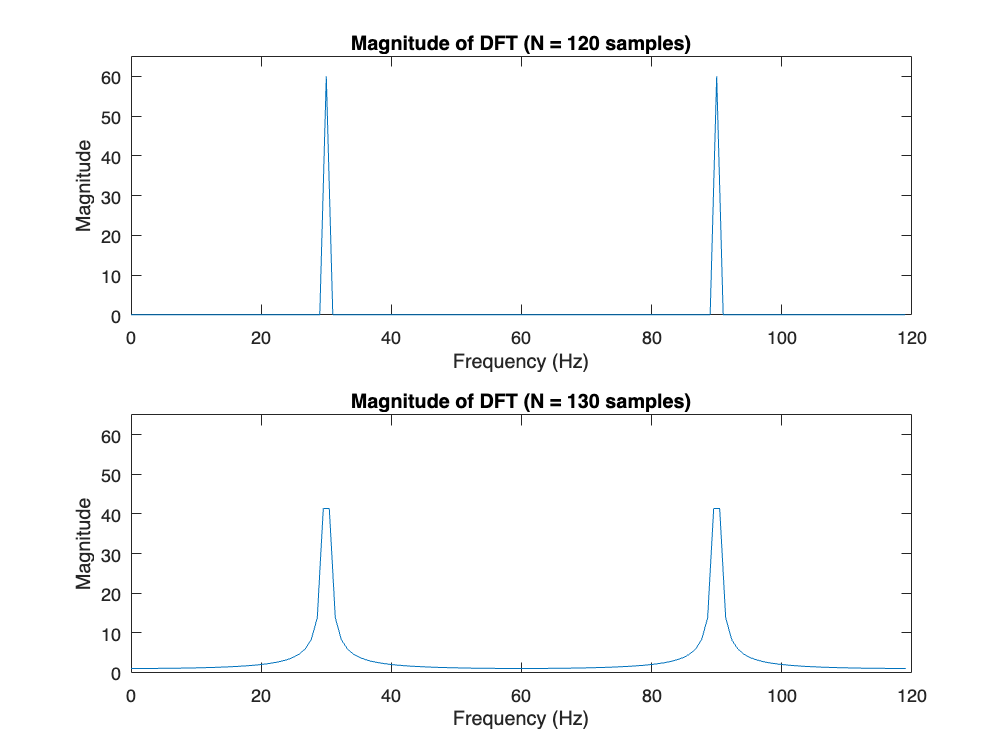

ylim([0 65])

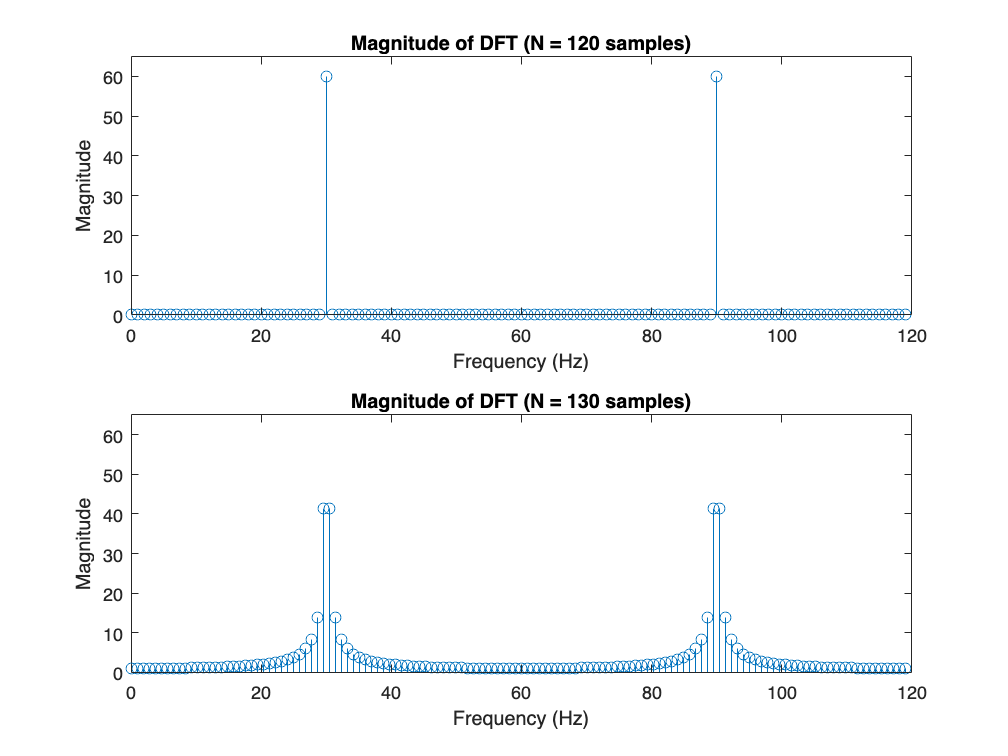


figure;
grid on
subplot(2, 1, 1);
stem(frequencies1, magnitude1);
title('Magnitude of DFT (N = 120 samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0 65])

subplot(2, 1, 2);
stem(frequencies2, magnitude2);
title('Magnitude of DFT (N = 130 samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0 65])


%3
N = find(all(dft1 == dft(1:N1)))


N =

     []

